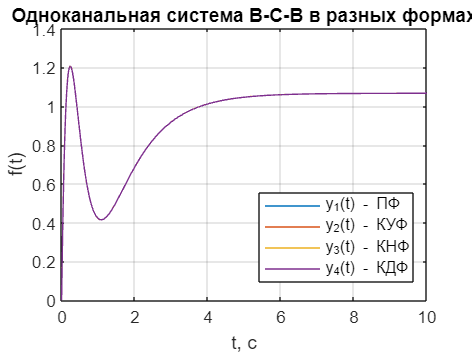

open_system('task2_1');
set_param('task2_1/y', 'VariableName', 'y')

out = sim('task2_1');

plot(out.y, 'DisplayName', 'y_1(t) - ПФ')
hold on
open_system('task2_2');
set_param('task2_2/y', 'VariableName', 'y')
out = sim('task2_2');

plot(out.y, 'DisplayName', 'y_2(t) - КУФ')
hold on

open_system('task2_3');
set_param('task2_3/y', 'VariableName', 'y')
out = sim('task2_3');

plot(out.y, 'DisplayName', 'y_3(t) - КНФ')
hold on
open_system('task2_4');
set_param('task2_4/y', 'VariableName', 'y')
out = sim('task2_4');

plot(out.y, 'DisplayName', 'y_4(t) - КДФ')
hold on
grid()
title('Одноканальная система В-С-В в разных формах')
legend("Position", [0.55737,0.20666,0.3125,0.24368])
ylabel('f(t)')
xlabel('t, с')